load humanactivity.mat

  Name                 Size               Bytes  Class     Attributes

  Description         29x1                 5918  string              
  actid            24075x1               192600  double              
  actnames             1x5                  592  cell                
  feat             24075x60            11556000  double              
  featlabels          60x1                 8292  cell                



whos

Description

Description = 29×1 string array
    "                        === Human Activity Data ===                        "
    "                                                                           "
    " The humanactivity data set contains 24,075 observations of five different "
    " physical human activities: Sitting, Standing, Walking, Running, and       "
    " Dancing. Each observation has 60 features extracted from acceleration     "
    " data measured by smartphone accelerometer sensors. The data set contains  "
    " the following variables:                                                  "
    "                                                                           "
    " * actid — Response vector containing the activity IDs in integers: 1, 2, "
    " 3, 4, and 5 representing Sitting, Standing, Walking, Running, and         "
    " Dancing, respectively                                                     "
    " * actnames — Activity names corresponding to the integer acti

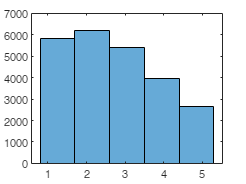

histogram(actid, 5)

% Atividade 2 tem mais observacoes


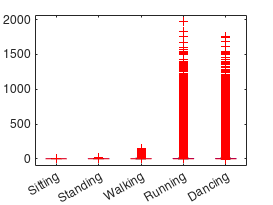


boxplot(feat', actnames(actid))

a5 = feat(actid == 5,:)

a5 = 1.0e+03 *

   -0.0002    0.0010   -0.0002    0.0003    0.0012    0.0004    0.0036   -0.0022    0.0002    0.0475   -0.0024    0.0030    0.0051   -0.0026    0.0001    0.0014    0.0018    0.0026    0.0033    0.0039    0.0050    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0013    0.0020    0.0034    0.0038    0.0047    0.0000    0.0003    0.0019    0.0003    0.0006    0.0002    0.0012    0.0018    0.0027    0.0034    0.0040    0.0050    0.0001    0.0001    0.0001    0.0001    0.0001
   -0.0002    0.0010   -0.0001    0.0003    0.0012    0.0004    0.0036   -0.0021    0.0002    0.0485   -0.0021    0.0060    0.0060   -0.0023    0.0008    0.0014    0.0019    0.0030    0.0033    0.0039    0.0050    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0019    0.0029    0.0033    0.0038    0.0048    0.0000    0.0025    0.0001    0.0004    0.0004    0.0001    0.0012    0.0018    0.0023    0.0026    0.0034    0.0040    0.0000    0.0001    0.0000   

variancias = var(a5)

variancias = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0009    0.0000    0.0000    0.0423    0.0000    0.0031    0.0052    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


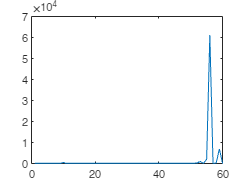

plot(variancias)

[maior_variancia, indice_feature] = max(variancias)

maior_variancia = 6.0988e+04

indice_feature = 56

nome_feature = featlabels{indice_feature}

nome_feature = 'BodyAccYPowerBand2'

indice_feature = find(strcmp(featlabels, 'BodyAccXRMS'))

indice_feature = 4

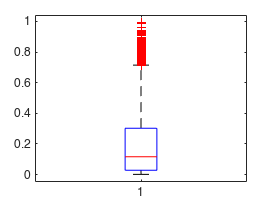

dados_feature4 = feat(:,indice_feature);
boxplot(dados_feature4)

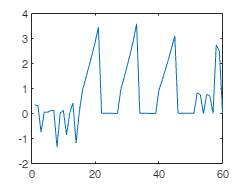

atividade_1 = feat(actid == 1, :);
media_features = mean(atividade_1);
plot(media_features);

media_global = mean(atividade_1, 'all')

media_global = 0.7265

desvio_padrao_global = std(atividade_1, 0, 'all')

desvio_padrao_global = 1.2355